# The AstFilter class

# in the Astronomy & Astrophysics package for MATLAB

## Description:

The AstFilter support excess and manipulation of astronomical telescope transmission filters. The class includes a structure-array like object that contains about 200 astronomical transmission filters. The user can add his/her own filters. Furthermore, the filters can be plotted, manipulated and other classes (e.g., AstSpec) can work with this class.

This file is accessible through "`AstFilter.manual`".

## Instellation

This class is available as part of the *Astronomy and Astrophysics toolbox for matlab*. Furthermore, some of the functions in this class use functions in other packages in the toolbox, so full instellation is recomended.

See [http://weizmann.ac.il/home/eofek/matlab](http://weizmann.ac.il/home/eofek/matlab) for instellation instruction and additional documentation.

The AstFilter class requires the AstFilterCat.mat file in the /data/Filters/ directory, as well as the @AstFilter directory in a directory contained in the MATLAB search path.

## The AstFilter object properties

The `AstFilter` object contains about 200 elements with the following properties:

family   - Filter family name (e.g., 'SDSS', 'Johnson','2MASS',...)

band    - Band name (e.g., 'u','U','K',...)

T          - A two elemnt matrix of transmission curve [Wavelength(Ang), Transmission]. 

Tunits  - Transmission units in T. If empty then the units may be arbitrary.

nT       - Normalized transmission matrix such that the integral is 1.

min_wl - Minimum wavelength

max_wl - Maximum wavelength

eff_wl    - Effective wavelength

half_width - Filter half width (kept for historical reasons)

fwhm        - Filter Full Width at Half Maximum

comments  - General comments

source        - Source

UserData    - Additional user data

# Methods an examples:

To see all the properties and methods (functions) associated with the `AstFilter` object, first define an AstFilter object:

AstF=AstFilter

 and than type:

AstF.<tab>

## Loading filters

The transmission filters are stored in a mat file named `AstFilterCat.m`.

To load the entire `AstFilter` object to memory use the static class:

F=AstFilter.get;

To see the content of F:

F

F =   191x1 AstFilter array with properties:

    family
    band
    T
    Tunits
    nT
    min_wl
    max_wl
    eff_wl
    half_width
    fwhm
    comments
    source
    UserData


You can also upload specific filters.

Loading all the SDSS family filters

F=AstFilter.get('SDSS');

or loading all the Filter named 'V'

AstFilter.get([],'V');

or a load several families

F = AstFilter.get({'PTF','sdss'});

You can search filters by a substring of family name:

F=AstFilter.get;
F=search(F,'sds')

F =   5x1 AstFilter array with properties:

    family
    band
    T
    Tunits
    nT
    min_wl
    max_wl
    eff_wl
    half_width
    fwhm
    comments
    source
    UserData


or to get all available filter families:

F=AstFilter.get;
all_family(F)

ans =   Columns 1 through 28

    '2MASS'    'Bessel'    'Cousins'    'DENIS'    'DES'    'GALEX'    'GuideStarCat'    'HST-ACS'    'HST-NICMOS'    'HST-WFPC2'    'Hipparcos'    'IRAS'    'Johnson'    'Johnson1965'    'KAIT'    'Kepler'    'LIM'    'POSS-I'    'POSS-II'    'PTF'    'ROSAT'    'ROSAT/WFC'    'Ratir'    'SDSS'    'Spitzer'    'Stromgren'    'SuprimeCam'    'Swift-UVOT'

  Columns 29 through 33

    'WFC3'    'WFC3/UVIS1'    'WFC3/UVIS2'    'WISE'    'temp'


## Plot functions

You can plot the filter transmission curves:

F=AstFilter.get('SDSS')

F =   5x1 AstFilter array with properties:

    family
    band
    T
    Tunits
    nT
    min_wl
    max_wl
    eff_wl
    half_width
    fwhm
    comments
    source
    UserData


ans =   Text (Normalized transmission) with properties:

                 String: 'Normalized transmission'
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'times'
                  Color: [0.15 0.15 0.15]
    HorizontalAlignment: 'center'
               Position: [2524.4 0.001 -1]
                  Units: 'data'

  Show all properties


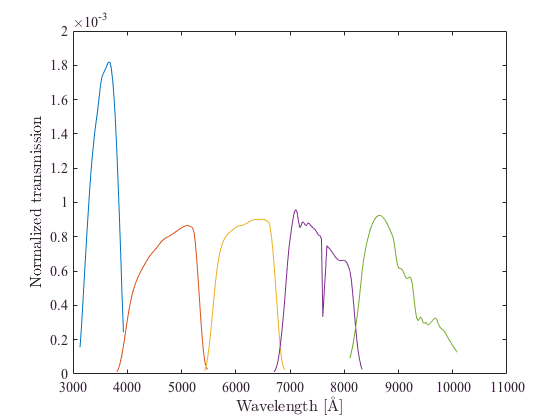

plot(F)

% or
stairs(F)

## Statistics

You can get some statistical properties of transmission curves using the

`integral`, `max_tran`, `max_wave`, and `norm`.

See help for more details

## Shift

You can shift (by redshift) a transmission curve. For example:

F=AstFilter.get('WFC3','F160W')

F =   AstFilter with properties:

        family: 'WFC3'
          band: 'f160w'
             T: [158x2 double]
        Tunits: []
            nT: [158x2 double]
        min_wl: 13840
        max_wl: 16980
        eff_wl: 15427
    half_width: 1429.9
          fwhm: 2860
      comments: 'JUST FILTERS WITHOUT OPTICS AND SYSTEM THROUPUT'
        source: 'FROM WFC3 website in 2008 : http://www.stsci.edu/hst/wfc3/ins_performance/ground/components/filters/'
      UserData: []


ans =   Text (Normalized transmission) with properties:

                 String: 'Normalized transmission'
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'times'
                  Color: [0.15 0.15 0.15]
    HorizontalAlignment: 'center'
               Position: [12406 0.0002 -1]
                  Units: 'data'

  Show all properties


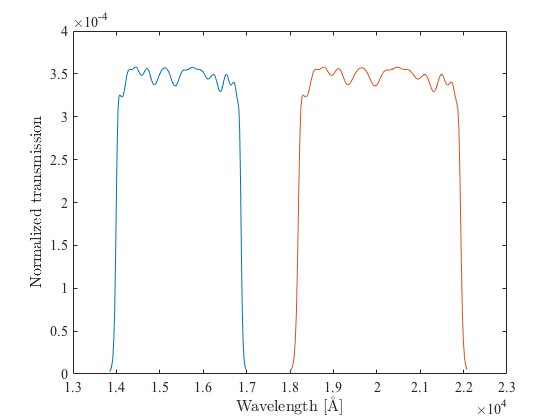

F1=shift(F,0.3);
plot([F;F1])

## Interpolation and sampling

Any operation of applying a transmission curve to e.g., a spectrum, or multiplication of several transmission curves requires that they will be resampled to the same grid.

The functions `interp`, `equalize_sampling`, `common_sampling` can be used for these purposes.

While `equalize_sampling `resample an `AstFilter` object to have the same sampling as another object, `common_sampling` is searching for the common wavelength range of two `AstFilter` objects and sample them to the same common wavelength range.

Examples:

F=AstFilter.get('SDSS');
Fu=interp(F(1),(3000:1:4000)')

Fu =   AstFilter with properties:

        family: 'SDSS'
          band: 'u'
             T: [1001x2 double]
        Tunits: []
            nT: [1001x2 double]
        min_wl: 3130
        max_wl: 3930
        eff_wl: 3560.9
    half_width: 292.56
          fwhm: 575
      comments: []
        source: []
      UserData: []


## Adding filters

To add your own filters, and populate the filters meta data information you can use the

`add_filter`, `pop_wl`, `save` functions.

See help for details.

Example:

% construct a new Filter
F=AstFilter;
% set the filter family and name
F.family='Ofek';
F.band  ='Eran';
% populate it with some filter shape (top-hat):
F.T = [4000 0; 4001 1; 4010 1; 4011 0];
% add the new filter F into the filters database in memory
F1  = add_filter(F);
% update the filter database on disk
% save(F1)   

Index exceeds matrix dimensions.

Error in interp1 (line 128)
        extptids = Xq < X(1) | Xq > X(end);

Error in AstFilter/pop_wl (line 580)
                AstF(If).half_width = interp1(CumSum+eps,Fnn(1:end-1,1),0.75) - ...

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('AstFilter/filter_fun2', '/Users/orlyg/eran/matlab/fun/class/@AstFilter/AstFilter.m', 650)" style="font-weigh

## Operators

To apply an arbitrary operator (unary or binary) to an AstFilter object you can use the `filter_fun1` and `filter_fun2` functions.

In addition many overload functions like `plus`, `minus`, `times`, `rdivide`, `lt`, `gt`, `le`, `ge`, `ne`, `eq` are available.

These functions first uses the `common_sampling` function and than perform the operation.

Examples:

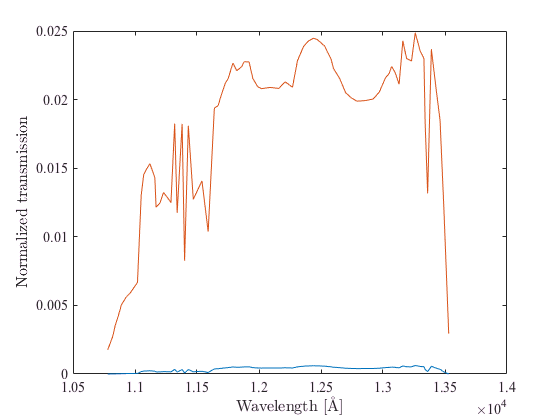

ans =   handle to deleted Text


ans =   Text (Normalized transmission) with properties:

                 String: 'Normalized transmission'
               FontSize: 16
             FontWeight: 'normal'
               FontName: 'times'
                  Color: [0.15 0.15 0.15]
    HorizontalAlignment: 'center'
               Position: [3793 0.0009 -1]
                  Units: 'data'

  Show all properties


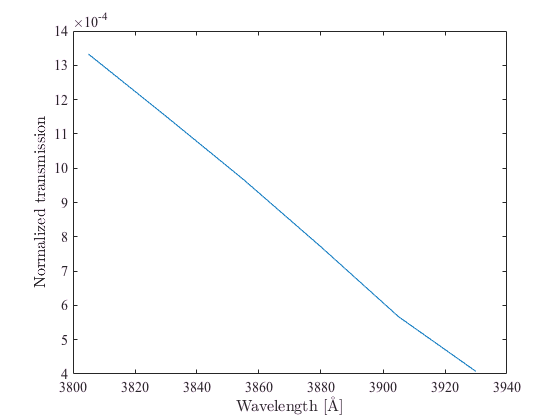

F=AstFilter.get('2MASS');
plot(F(1));
hold on;
plot(filter_fun1(F(1),@sqrt))

## Interacation with other classes and external functions

The AstFilter class is optionally used by other classes and functions.

For example, the `synphot` function to calculate synthetic photometry can work with the `AstFilter` class.